# Próbkowanie sygnałów ciągłych

clear. clc

syms t x w K

Częstotliwość próbkowania 

fp = 200; 
wp = 2*pi*fp;

Częstotliwość graniczna:

fg = fp/2; %Hz
wg = 2*pi*fg;

Generowanie sinusa:

s = 4/5; 
ws = s*wg;
x_sin = sin(ws*t);

X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp,10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2)];
BND_w = [-4*wp,4*wp];
w_SMP = BND_w(1):wp/10:BND_w(2);

figure;

subplot(2,1,1); 
hold on; 
grid on;

fplot(FILT_FT, BND_w); %okno filtru rek.ez
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);

stem(w_SMP(n),sign(v_num(n)),'r*');
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
fplot(x_sin, BND_t);

% syg. próbkowany
fplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
% % % % % % % % % hold off

## Zadanie 2

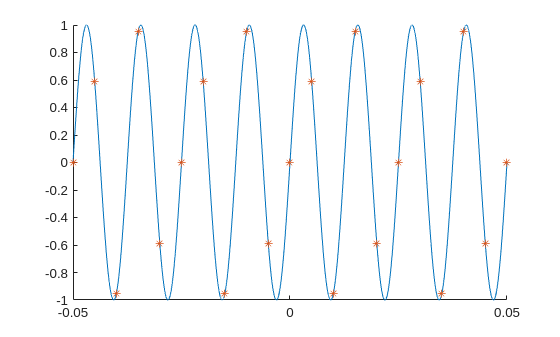

tt = BND_t(1):1/fp:BND_t(2);
figure();
hold on;
fplot(x_sin, BND_t)
plot(tt,sin(ws*tt),"*")

X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

## Zadanie 3

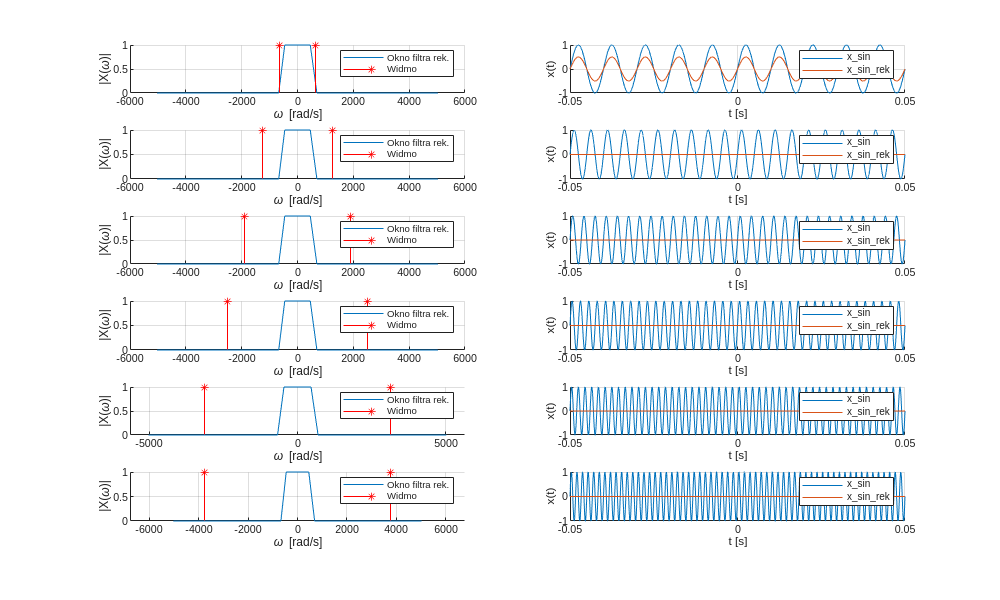

$$X\_FT\_sin = -\pi \,\left(\delta (w-200\,\pi )-\delta (w+200\,\pi )\right)\,\mathrm{i}$$

$$X\_FT\_sin = -\pi \,\left(\delta (w-400\,\pi )-\delta (w+400\,\pi )\right)\,\mathrm{i}$$

$$X\_FT\_sin = -\pi \,\left(\delta (w-600\,\pi )-\delta (w+600\,\pi )\right)\,\mathrm{i}$$

$$X\_FT\_sin = -\pi \,\left(\delta (w-800\,\pi )-\delta (w+800\,\pi )\right)\,\mathrm{i}$$

$$X\_FT\_sin = -\pi \,\left(\delta (w-1000\,\pi )-\delta (w+1000\,\pi )\right)\,\mathrm{i}$$

$$X\_FT\_sin = -\pi \,\left(\delta (w-1200\,\pi )-\delta (w+1200\,\pi )\right)\,\mathrm{i}$$

s_val = [1/5, 6/5, 11/5, 16/5, 4/5, 9/5, 14/5];

figure(Position=[100, 100, 1000, 600])
for s = 1:6
    ws = s*wg;
    x_sin = sin(ws*t);
    
    X_FT_sin_org = fourier(x_sin);
    X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp,10/fp];

    subplot(6,2,2*s-1); 
    hold on; 
    grid on;
    
    fplot(FILT_FT, BND_w); %okno filtru rek.ez + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
    % % %ezplot(X_FT_sin,BND_w)
    v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
    n = find(abs(v_num) == Inf);
    
    stem(w_SMP(n),sign(v_num(n)),'r*');
    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    
    subplot(6,2,2*s); hold on; grid on;
    fplot(x_sin, BND_t);
    
    % syg. próbkowany
    fplot(x_sin_rek, BND_t) % syg. odtworzony
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_sin','x\_sin\_rek');
end

## Zadanie 4